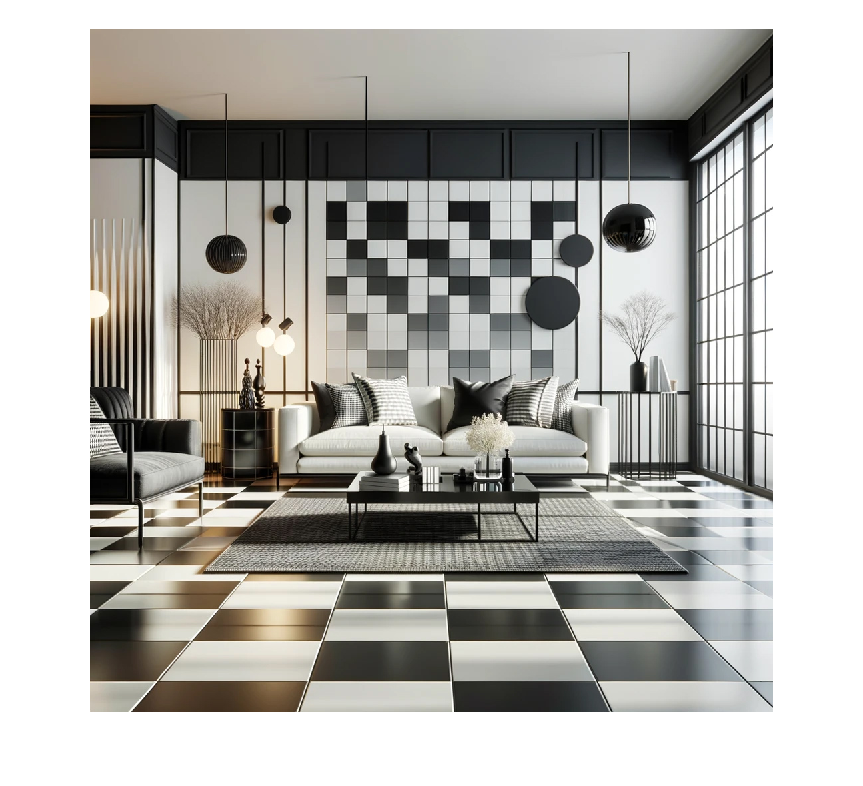

clear all;
% Bild laden
bildmatrix = imread('wohnzimmer.jpg');
imshow(bildmatrix);

figure;
% Parameter für die Wellen
wellenlaenge = 750; % Beispielwert
amplitude = 8; % Beispielwert

% Funktion aufrufen
disp(sin(2 * pi * 383 / 750))

   -0.0670



disp(round(8 * sin(2 * pi * 383 / 750)))

    -1



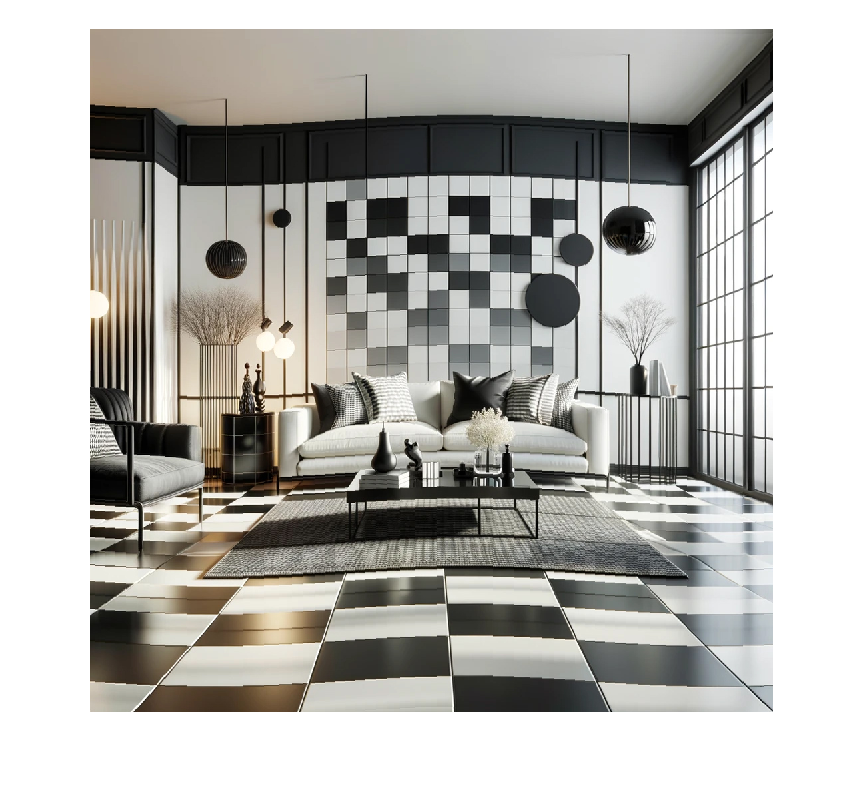

ergebnis = wellenEffekt(bildmatrix, wellenlaenge, amplitude);
imshow(ergebnis);

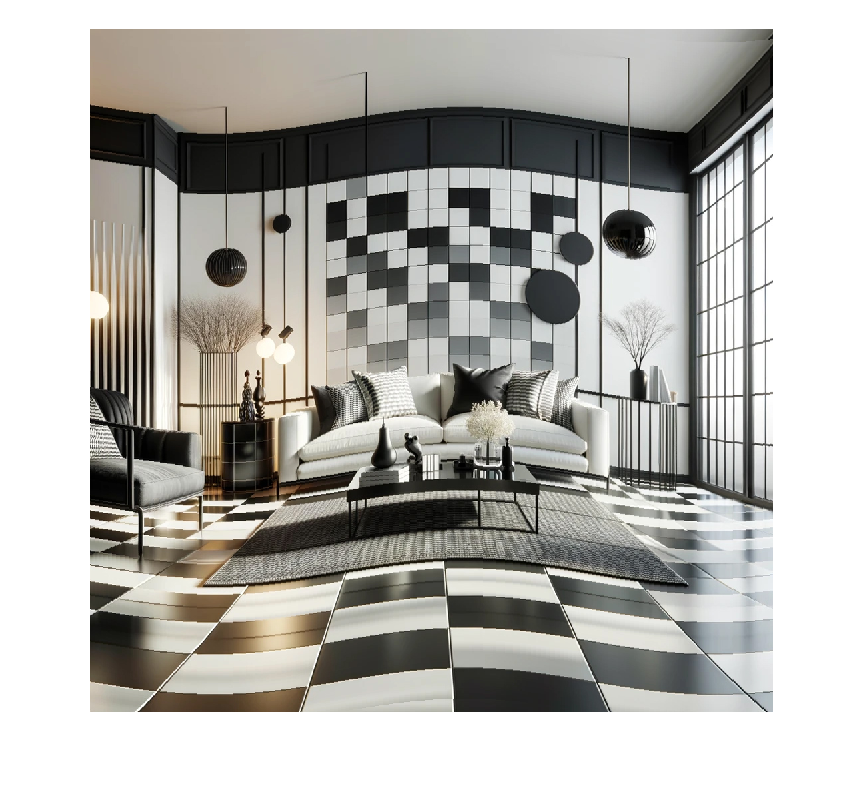

figure;
ergebnis1 = wellenEffekt(bildmatrix, wellenlaenge, 20);
imshow(ergebnis1);

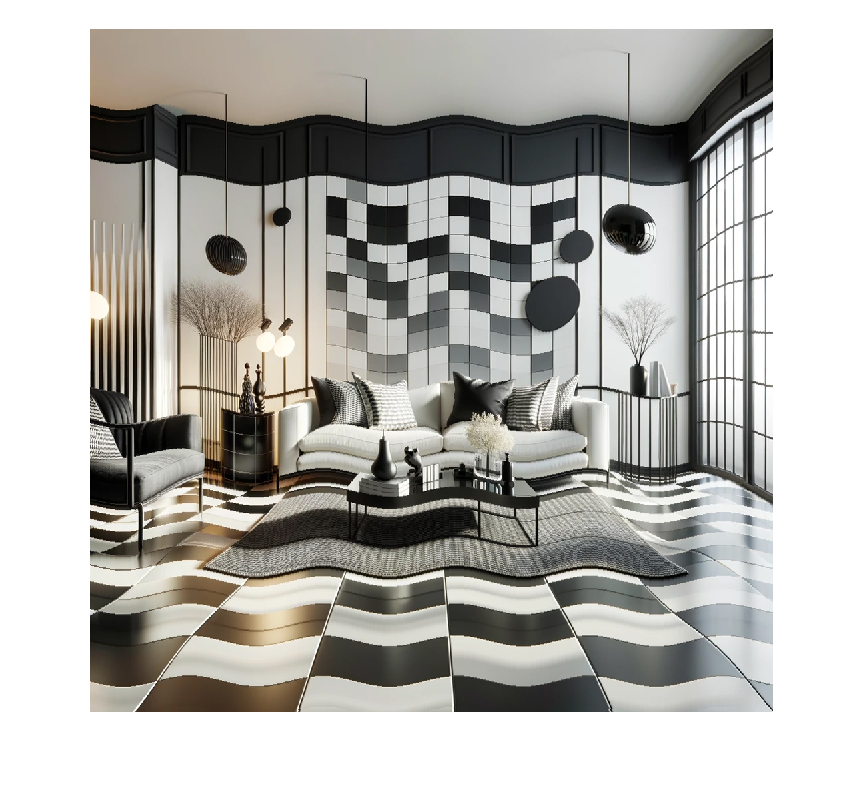

figure;
ergebnis11 = wellenEffekt(bildmatrix, 200, amplitude);
imshow(ergebnis11);

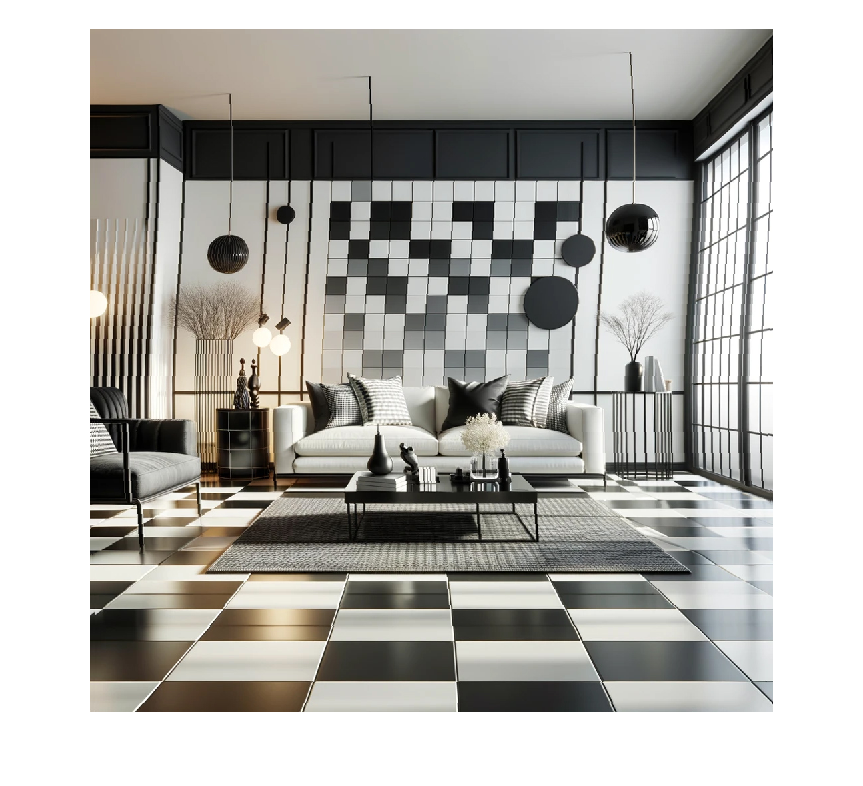


figure;
ergebnis2 = wellenEffekt2(bildmatrix, wellenlaenge, amplitude);
imshow(ergebnis2);

% Ergebnis speichern
imwrite(ergebnis, 'ergebnisbild.jpg');
disp(8*sin(2*pi*8/750))

    0.5358



%Abhängig von der Spalte --> shiften zeile

function [bildwellen] = wellenEffekt(bildmatrix, wellenlaenge, amplitude)
    [zeilen, spalten, ~] = size(bildmatrix);
    bildwellen = bildmatrix;
    % zeros(size(bildmatrix), 'like', bildmatrix);
    
    for spalte = 1:spalten
        shift = round(amplitude * sin(2 * pi * spalte / wellenlaenge));
        for zeile = 1:zeilen
            neueZeile = zeile + shift;
            neueSpalte = spalte;
            if neueZeile > 0 && neueZeile <= zeilen
                bildwellen(neueZeile, neueSpalte, :) = bildmatrix(zeile, spalte, :);
            end
        end
    end
end
%Abhängig von der Zeile
function [bildwellen] = wellenEffekt2(bildmatrix, wellenlaenge, amplitude)
    [zeilen, spalten, ~] = size(bildmatrix);
    bildwellen = bildmatrix;
    % zeros(size(bildmatrix), 'like', bildmatrix);
    
    for zeile = 1:zeilen
        shift = round(amplitude * sin(2 * pi * zeile / wellenlaenge ));
        for spalte = 1:spalten
            neueSpalte = spalte + shift;
            neueZeile = zeile;
            if neueSpalte > 0 && neueSpalte <= spalten
                bildwellen(neueZeile, neueSpalte, :) = bildmatrix(zeile, spalte, :);
            end
        end
    end
end

function [bildwellen] = wellenEffekt3(bildmatrix, wellenlaenge, amplitude)
    [zeilen, spalten, ~] = size(bildmatrix);
    bildwellen = bildmatrix;
    % zeros(size(bildmatrix), 'like', bildmatrix);
    
    for spalte = 1:spalten
        shift = round(amplitude * sin(2 * pi * spalte / wellenlaenge)-100);
        for zeile = 1:zeilen
            neueZeile = zeile + shift;
            neueSpalte = spalte;
            if neueZeile > 0 && neueZeile <= zeilen
                bildwellen(neueZeile, neueSpalte, :) = bildmatrix(zeile, spalte, :);
            end
        end
    end
end
